mfccLength = 18;
class1 = 'TURMER';
class2 = 'LUSMEG';

## Blackbird vs Nightingale binary SVM classification

TURMER_mfcc = buildFeatureMatrix(class1,mfccLength);
LUSMEG_mfcc = buildFeatureMatrix(class2,mfccLength);

XTrain = [TURMER_mfcc;LUSMEG_mfcc];
YTrain = ones(size(XTrain,1),1);
YTrain(1:size(TURMER_mfcc,1)) = -1;

mfccLinearSvmTURMERxLUSMEG = fitcsvm(XTrain,YTrain,'KernelFunction','linear',...
    'Standardize',true,'ClassNames',[-1,1]);

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | BoxConstraint|  KernelScale |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |      0.4732 |       27.34 |      0.4732 |      0.4732 |     0.001888 |       807.63 |
|    2 | Accept |      0.4732 |      27.601 |      0.4732 |      0.4732 |       596.46 |     0.020911 |
|    3 | Accept |      0.4732 |      29.952 |      0.4732 |      0.4732 |      0.25774 |    0.0052507 |
|    4 | Best   |     0.20206 |      20.854 |     0.20206 |     0.20209 |       631.45 |       211.82 |
|    5 | Best   |     0.19381 |      31.377 |     0.19381 |     0.19386 |       968.26 |       79.294 |
|    6 | Best   |     0.19175 |      19.609 |     0.19175 |     

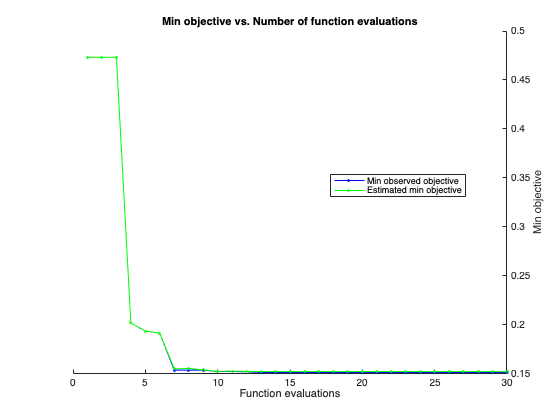

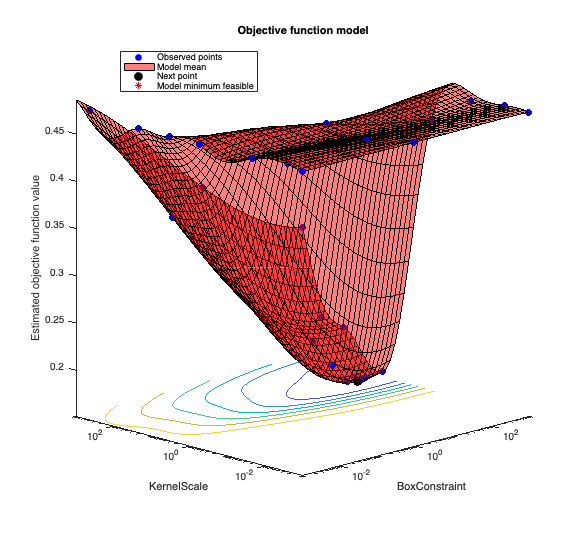


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 808.0313 seconds
Total objective function evaluation time: 775.6766

Best observed feasible point:
    BoxConstraint    KernelScale
    _____________    ___________

       308.85          9.5928   

Observed objective function value = 0.15155
Estimated objective function value = 0.15242
Function evaluation time = 21.7062

Best estimated feasible point (according to models):
    BoxConstraint    KernelScale
    _____________    ___________

       308.85          9.5928   

Estimated objective function value = 0.15242
Estimated function evaluation time = 24.1971



mfccRBFSvmTURMERxLUSMEG =   ClassificationSVM
                         ResponseName: 'Y'
                CategoricalPredictors: []
                           ClassNames: [-1 1]
                       ScoreTransform: 'none'
                      NumObservations: 2910
    HyperparameterOptimizationResults: [1×1 BayesianOptimization]
                                Alpha: [1684×1 double]
                                 Bias: 0.1911
                     KernelParameters: [1×1 struct]
                       BoxConstraints: [2910×1 double]
                      ConvergenceInfo: [1×1 struct]
                      IsSupportVector: [2910×1 logical]
                               Solver: 'SMO'


  Properties, Methods


c = cvpartition(size(XTrain,1),'KFold',7);
opts = struct('CVPartition',c,'AcquisitionFunctionName','expected-improvement-plus');
mfccRBFSvmTURMERxLUSMEG = fitcsvm(XTrain,YTrain,'KernelFunction','rbf', ...
    'OptimizeHyperparameters','auto', 'ClassNames',[-1,1], ...
    'HyperparameterOptimizationOptions',opts)

## Testing PCA

TURMER_mfcc = buildFeatureMatrix(class1,mfccLength);
LUSMEG_mfcc = buildFeatureMatrix(class2,mfccLength);

XTrain = [TURMER_mfcc;LUSMEG_mfcc];
YTrain = ones(size(XTrain,1),1);
YTrain(1:size(TURMER_mfcc,1)) = -1;

[XTrain95,mfccCoeffs95] = projectPCA(XTrain,95);

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | BoxConstraint|  KernelScale |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |      0.4732 |      2.0286 |      0.4732 |      0.4732 |    0.0053264 |     0.060703 |
|    2 | Accept |      0.4732 |      1.8195 |      0.4732 |      0.4732 |    0.0021036 |        210.4 |
|    3 | Best   |     0.45704 |      2.1135 |     0.45704 |     0.45705 |        5.024 |     0.021253 |
|    4 | Best   |     0.35876 |       2.022 |     0.35876 |     0.35877 |       0.8818 |       196.31 |
|    5 | Accept |     0.35945 |      2.6151 |     0.35876 |     0.35877 |      0.53684 |       140.11 |
|    6 | Accept |     0.35979 |      1.3725 |     0.35876 |     


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 253.5775 seconds
Total objective function evaluation time: 223.8009

Best observed feasible point:
    BoxConstraint    KernelScale
    _____________    ___________

       2.8724          3.8748   

Observed objective function value = 0.30344
Estimated objective function value = 0.30519
Function evaluation time = 1.7356

Best estimated feasible point (according to models):
    BoxConstraint    KernelScale
    _____________    ___________

       3.0727          3.7553   

Estimated objective function value = 0.30521
Estimated function evaluation time = 1.8117



mfccRBFSvmTURMERxLUSMEG95 =   ClassificationSVM
                         ResponseName: 'Y'
                CategoricalPredictors: []
                           ClassNames: [-1 1]
                       ScoreTransform: 'none'
                      NumObservations: 2910
    HyperparameterOptimizationResults: [1×1 BayesianOptimization]
                                Alpha: [2087×1 double]
                                 Bias: 0.0051
                     KernelParameters: [1×1 struct]
                       BoxConstraints: [2910×1 double]
                      ConvergenceInfo: [1×1 struct]
                      IsSupportVector: [2910×1 logical]
                               Solver: 'SMO'


  Properties, Methods


mfccLinearSvmTURMERxLUSMEG95 = fitcsvm(XTrain95,YTrain,'KernelFunction','linear',...
    'Standardize',true,'ClassNames',[-1,1]);
c = cvpartition(size(XTrain95,1),'KFold',7);
opts = struct('CVPartition',c,'AcquisitionFunctionName','expected-improvement-plus');
mfccRBFSvmTURMERxLUSMEG95 = fitcsvm(XTrain95,YTrain,'KernelFunction','rbf', ...
    'OptimizeHyperparameters','auto', 'ClassNames',[-1,1], ...
    'HyperparameterOptimizationOptions',opts)

### With 99% variance captured with PCA

[XTrain99,mfccCoeffs99] = projectPCA(XTrain,99);

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | BoxConstraint|  KernelScale |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |     0.33608 |      1.9697 |     0.33608 |     0.33608 |       1.7905 |       38.082 |
|    2 | Accept |      0.4457 |      7.0728 |     0.33608 |     0.34442 |        304.6 |     0.063998 |
|    3 | Accept |      0.4732 |       2.975 |     0.33608 |     0.33609 |     0.010885 |     0.012348 |
|    4 | Accept |      0.4732 |      1.5742 |     0.33608 |      0.3361 |    0.0040984 |       6.0088 |
|    5 | Accept |     0.35876 |      2.1904 |     0.33608 |     0.33611 |       4.8172 |       978.54 |
|    6 | Accept |     0.44708 |      1.6249 |     0.33608 |     


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 782.1886 seconds
Total objective function evaluation time: 202.4827

Best observed feasible point:
    BoxConstraint    KernelScale
    _____________    ___________

       54.144          22.045   

Observed objective function value = 0.31615
Estimated objective function value = 0.31831
Function evaluation time = 3.2206

Best estimated feasible point (according to models):
    BoxConstraint    KernelScale
    _____________    ___________

       15.379           18.61   

Estimated objective function value = 0.31707
Estimated function evaluation time = 2.6212



mfccRBFSvmTURMERxLUSMEG99 =   ClassificationSVM
                         ResponseName: 'Y'
                CategoricalPredictors: []
                           ClassNames: [-1 1]
                       ScoreTransform: 'none'
                      NumObservations: 2910
    HyperparameterOptimizationResults: [1×1 BayesianOptimization]
                                Alpha: [1947×1 double]
                                 Bias: 0.8604
                     KernelParameters: [1×1 struct]
                       BoxConstraints: [2910×1 double]
                      ConvergenceInfo: [1×1 struct]
                      IsSupportVector: [2910×1 logical]
                               Solver: 'SMO'


  Properties, Methods


mfccLinearSvmTURMERxLUSMEG99 = fitcsvm(XTrain99,YTrain,'KernelFunction','linear',...
    'Standardize',true,'ClassNames',[-1,1]);
c = cvpartition(size(XTrain99,1),'KFold',7);
opts = struct('CVPartition',c,'AcquisitionFunctionName','expected-improvement-plus');
mfccRBFSvmTURMERxLUSMEG99 = fitcsvm(XTrain99,YTrain,'KernelFunction','rbf', ...
    'OptimizeHyperparameters','auto', 'ClassNames',[-1,1], ...
    'HyperparameterOptimizationOptions',opts)

accuracyFullFreqRange = {};
test1 = buildFeatureMatrix(class1,mfccLength,'test');
test2 = buildFeatureMatrix(class2,mfccLength,'test');
testMatrix = {test1; test2};
testMatrix95 = {test1 * mfccCoeffs95; test2 * mfccCoeffs95};
testMatrix99 = {test1 * mfccCoeffs99; test2 * mfccCoeffs99};
testMatrices = {testMatrix;testMatrix95;testMatrix99};
modelsFull = {mfccLinearSvmTURMERxLUSMEG;mfccRBFSvmTURMERxLUSMEG};
models95 = {mfccLinearSvmTURMERxLUSMEG95;mfccRBFSvmTURMERxLUSMEG95};
models99 = {mfccLinearSvmTURMERxLUSMEG99;mfccRBFSvmTURMERxLUSMEG99};
models = {modelsFull;models95;models99};
for i = 1:3 % var
    for j = 1:2 % model type
        t1 = testMatrices{i}{1};
        t2 = testMatrices{i}{2};
        m = models{i}{j};
        acc1 = testModel(t1,-1,m);
        acc2 = testModel(t2,1,m);
        accuracyFullFreqRange{j,i} = [acc1,acc2];
    end
end

test1 = buildFeatureMatrix(class1,mfccLength,'test');
test2 = buildFeatureMatrix(class2,mfccLength,'test');

testModel(test2,1,mfccRBFSvmTURMERxLUSMEG)

ans = 0.6353

mfccTableFullFreqRange = table();
mfccTableFullFreqRange.('Full model') = accuracyFullFreqRange(:,1);
mfccTableFullFreqRange.('95% var PCA') = accuracyFullFreqRange(:,2);
mfccTableFullFreqRange.('99% var PCA') = accuracyFullFreqRange(:,3);
mfccTableFullFreqRange.Properties.RowNames = {'Linear','RBF'};

## Testing different frequency ranges

freqExperiment1Range = linspace(500,12000,42);

TURMER_mfcc = buildFeatureMatrix(class1,mfccLength,'train',false,freqExperiment1Range);
LUSMEG_mfcc = buildFeatureMatrix(class2,mfccLength,'train',false,freqExperiment1Range);

XTrain = [TURMER_mfcc;LUSMEG_mfcc];
YTrain = ones(size(XTrain,1),1);
YTrain(1:size(TURMER_mfcc,1)) = -1;

mfccLinearSvmTURMERxLUSMEG = fitcsvm(XTrain,YTrain,'KernelFunction','linear',...
    'Standardize',true,'ClassNames',[-1,1]);
c = cvpartition(size(XTrain,1),'KFold',7);
opts = struct('CVPartition',c,'AcquisitionFunctionName','expected-improvement-plus');
mfccRBFSvmTURMERxLUSMEG = fitcsvm(XTrain,YTrain,'KernelFunction','rbf', ...
    'OptimizeHyperparameters','auto', 'ClassNames',[-1,1], ...
    'HyperparameterOptimizationOptions',opts)

[~,mfccCoeffs95] = projectPCA(XTrain,95);
mfccLinearSvmTURMERxLUSMEG95 = fitcsvm(XTrain95,YTrain,'KernelFunction','linear',...
    'Standardize',true,'ClassNames',[-1,1]);
c = cvpartition(size(XTrain95,1),'KFold',7);
opts = struct('CVPartition',c,'AcquisitionFunctionName','expected-improvement-plus');
mfccRBFSvmTURMERxLUSMEG95 = fitcsvm(XTrain95,YTrain,'KernelFunction','rbf', ...
    'OptimizeHyperparameters','auto', 'ClassNames',[-1,1], ...
    'HyperparameterOptimizationOptions',opts)

[~,mfccCoeffs99] = projectPCA(XTrain,99);
mfccLinearSvmTURMERxLUSMEG99 = fitcsvm(XTrain99,YTrain,'KernelFunction','linear',...
    'Standardize',true,'ClassNames',[-1,1]);
c = cvpartition(size(XTrain99,1),'KFold',7);
opts = struct('CVPartition',c,'AcquisitionFunctionName','expected-improvement-plus');
mfccRBFSvmTURMERxLUSMEG99 = fitcsvm(XTrain99,YTrain,'KernelFunction','rbf', ...
    'OptimizeHyperparameters','auto', 'ClassNames',[-1,1], ...
    'HyperparameterOptimizationOptions',opts)

accuracyFreqRangeExperiment1 = {};
test1 = buildFeatureMatrix(class1,mfccLength,'test',false,freqExperiment1Range);
test2 = buildFeatureMatrix(class2,mfccLength,'test',false,freqExperiment1Range);
testMatrix = {test1; test2};
testMatrix95 = {test1 * mfccCoeffs95; test2 * mfccCoeffs95};
testMatrix99 = {test1 * mfccCoeffs99; test2 * mfccCoeffs99};
testMatrices = {testMatrix;testMatrix95;testMatrix99};
modelsFull = {mfccLinearSvmTURMERxLUSMEG;mfccRBFSvmTURMERxLUSMEG};
models95 = {mfccLinearSvmTURMERxLUSMEG95;mfccRBFSvmTURMERxLUSMEG95};
models99 = {mfccLinearSvmTURMERxLUSMEG99;mfccRBFSvmTURMERxLUSMEG99};
models = {modelsFull;models95;models99};
for i = 1:3 % var
    for j = 1:2 % model type
        t1 = testMatrices{i}{1};
        t2 = testMatrices{i}{2};
        m = models{i}{j};
        acc1 = testModel(t1,-1,m);
        acc2 = testModel(t2,1,m);
        accuracyFreqRangeExperiment1{j,i} = [acc1,acc2];
    end
end

mfccTableFreqRangeExperiment1 = table();
mfccTableFreqRangeExperiment1.('Full model') = accuracyFreqRangeExperiment1(:,1);
mfccTableFreqRangeExperiment1.('95% var PCA') = accuracyFreqRangeExperiment1(:,2);
mfccTableFreqRangeExperiment1.('99% var PCA') = accuracyFreqRangeExperiment1(:,3);
mfccTableFreqRangeExperiment1.Properties.RowNames = {'Linear','RBF'};
mfccTableFreqRangeExperiment1

mfccTableFreqRangeExperiment1 = 2×3 table
                 Full model           95% var PCA          99% var PCA   
              _________________    _________________    _________________

    Linear    {[0.6382 0.8271]}    {[0.4548 0.9455]}    {[0.4238 0.9624]}
    RBF       {[0.7984 0.6617]}    {[0.6279 0.7274]}    {[0.6460 0.6936]}


### Experiment 2: wider range (50-22050Hz)

freqExperiment2Range = linspace(50,22050,42);

TURMER_mfcc = buildFeatureMatrix(class1,mfccLength,'train',false,freqExperiment2Range);
LUSMEG_mfcc = buildFeatureMatrix(class2,mfccLength,'train',false,freqExperiment2Range);

XTrain = [TURMER_mfcc;LUSMEG_mfcc];
YTrain = ones(size(XTrain,1),1);
YTrain(1:size(TURMER_mfcc,1)) = -1;

mfccLinearSvmTURMERxLUSMEG = fitcsvm(XTrain,YTrain,'KernelFunction','linear',...
    'Standardize',true,'ClassNames',[-1,1]);
c = cvpartition(size(XTrain,1),'KFold',7);
opts = struct('CVPartition',c,'AcquisitionFunctionName','expected-improvement-plus');
mfccRBFSvmTURMERxLUSMEG = fitcsvm(XTrain,YTrain,'KernelFunction','rbf', ...
    'OptimizeHyperparameters','auto', 'ClassNames',[-1,1], ...
    'HyperparameterOptimizationOptions',opts)

[~,mfccCoeffs95] = projectPCA(XTrain,95);
mfccLinearSvmTURMERxLUSMEG95 = fitcsvm(XTrain95,YTrain,'KernelFunction','linear',...
    'Standardize',true,'ClassNames',[-1,1]);
c = cvpartition(size(XTrain95,1),'KFold',7);
opts = struct('CVPartition',c,'AcquisitionFunctionName','expected-improvement-plus');
mfccRBFSvmTURMERxLUSMEG95 = fitcsvm(XTrain95,YTrain,'KernelFunction','rbf', ...
    'OptimizeHyperparameters','auto', 'ClassNames',[-1,1], ...
    'HyperparameterOptimizationOptions',opts)

[~,mfccCoeffs99] = projectPCA(XTrain,99);

mfccLinearSvmTURMERxLUSMEG99 = fitcsvm(XTrain99,YTrain,'KernelFunction','linear',...
    'Standardize',true,'ClassNames',[-1,1]);

c = cvpartition(size(XTrain99,1),'KFold',7);
opts = struct('CVPartition',c,'AcquisitionFunctionName','expected-improvement-plus');
mfccRBFSvmTURMERxLUSMEG99 = fitcsvm(XTrain99,YTrain,'KernelFunction','rbf', ...
    'OptimizeHyperparameters','auto', 'ClassNames',[-1,1], ...
    'HyperparameterOptimizationOptions',opts)

accuracyFreqRangeExperiment2 = {};
test1 = buildFeatureMatrix(class1,mfccLength,'test',false,freqExperiment2Range);
test2 = buildFeatureMatrix(class2,mfccLength,'test',false,freqExperiment2Range);
testMatrix = {test1; test2};
testMatrix95 = {test1 * mfccCoeffs95; test2 * mfccCoeffs95};
testMatrix99 = {test1 * mfccCoeffs99; test2 * mfccCoeffs99};
testMatrices = {testMatrix;testMatrix95;testMatrix99};
modelsFull = {mfccLinearSvmTURMERxLUSMEG;mfccRBFSvmTURMERxLUSMEG};
models95 = {mfccLinearSvmTURMERxLUSMEG95;mfccRBFSvmTURMERxLUSMEG95};
models99 = {mfccLinearSvmTURMERxLUSMEG99;mfccRBFSvmTURMERxLUSMEG99};
models = {modelsFull;models95;models99};
for i = 1:3 % var
    for j = 1:2 % model type
        t1 = testMatrices{i}{1};
        t2 = testMatrices{i}{2};
        m = models{i}{j};
        acc1 = testModel(t1,-1,m);
        acc2 = testModel(t2,1,m);
        accuracyFreqRangeExperiment2{j,i} = [acc1,acc2];
    end
end

mfccTableFreqRangeExperiment2 = table();
mfccTableFreqRangeExperiment2.('Full model') = accuracyFreqRangeExperiment2(:,1);
mfccTableFreqRangeExperiment2.('95% var PCA') = accuracyFreqRangeExperiment2(:,2);
mfccTableFreqRangeExperiment2.('99% var PCA') = accuracyFreqRangeExperiment2(:,3);
mfccTableFreqRangeExperiment2.Properties.RowNames = {'Linear','RBF'};
mfccTableFreqRangeExperiment2

mfccTableFreqRangeExperiment2 = 2×3 table
                 Full model           95% var PCA          99% var PCA   
              _________________    _________________    _________________

    Linear    {[0.7545 0.8515]}    {[0.4548 0.9455]}    {[0.4238 0.9624]}
    RBF       {[0.8062 0.7068]}    {[0.6072 0.6447]}    {[0.6047 0.6523]}


### Experiment 3: max range (50-fs/2)

freqExperiment3Range = "max";

TURMER_mfcc = buildFeatureMatrix(class1,mfccLength,'train',false,freqExperiment3Range);
LUSMEG_mfcc = buildFeatureMatrix(class2,mfccLength,'train',false,freqExperiment3Range);

XTrain = [TURMER_mfcc;LUSMEG_mfcc];
YTrain = ones(size(XTrain,1),1);
YTrain(1:size(TURMER_mfcc,1)) = -1;

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | BoxConstraint|  KernelScale |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |     0.35636 |      24.514 |     0.35636 |     0.35636 |       19.838 |       915.14 |
|    2 | Accept |     0.46838 |      28.361 |     0.35636 |     0.36394 |        87.73 |      0.16013 |
|    3 | Accept |     0.40378 |       30.26 |     0.35636 |     0.36037 |      0.14188 |       4.2911 |
|    4 | Accept |      0.4732 |      38.249 |     0.35636 |     0.35636 |      0.04198 |    0.0019732 |
|    5 | Best   |     0.35223 |      23.125 |     0.35223 |     0.35226 |     0.073326 |       199.73 |
|    6 | Best   |     0.21546 |      19.943 |     0.21546 |     

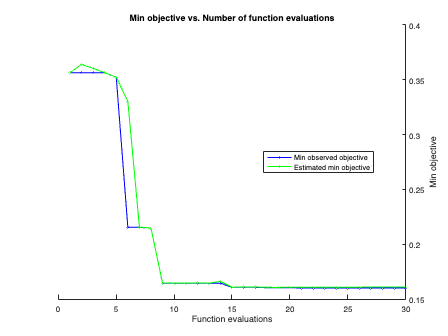

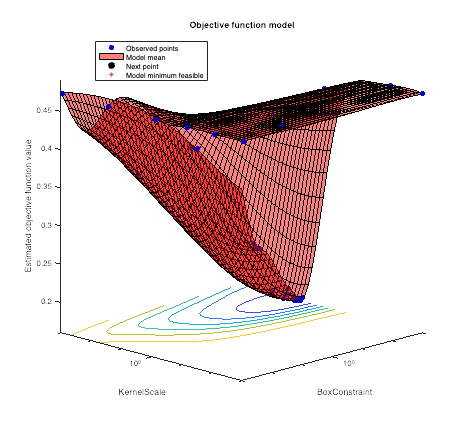


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 925.1858 seconds
Total objective function evaluation time: 875.086

Best observed feasible point:
    BoxConstraint    KernelScale
    _____________    ___________

       945.44          11.157   

Observed objective function value = 0.16014
Estimated objective function value = 0.16109
Function evaluation time = 23.4146

Best estimated feasible point (according to models):
    BoxConstraint    KernelScale
    _____________    ___________

       945.44          11.157   

Estimated objective function value = 0.16109
Estimated function evaluation time = 23.8802



mfccRBFSvmTURMERxLUSMEG =   ClassificationSVM
                         ResponseName: 'Y'
                CategoricalPredictors: []
                           ClassNames: [-1 1]
                       ScoreTransform: 'none'
                      NumObservations: 2910
    HyperparameterOptimizationResults: [1×1 BayesianOptimization]
                                Alpha: [1582×1 double]
                                 Bias: 0.5653
                     KernelParameters: [1×1 struct]
                       BoxConstraints: [2910×1 double]
                      ConvergenceInfo: [1×1 struct]
                      IsSupportVector: [2910×1 logical]
                               Solver: 'SMO'


  Properties, Methods


mfccLinearSvmTURMERxLUSMEG = fitcsvm(XTrain,YTrain,'KernelFunction','linear',...
    'Standardize',true,'ClassNames',[-1,1]);
c = cvpartition(size(XTrain,1),'KFold',7);
opts = struct('CVPartition',c,'AcquisitionFunctionName','expected-improvement-plus');
mfccRBFSvmTURMERxLUSMEG = fitcsvm(XTrain,YTrain,'KernelFunction','rbf', ...
    'OptimizeHyperparameters','auto', 'ClassNames',[-1,1], ...
    'HyperparameterOptimizationOptions',opts)

[XTrain95,mfccCoeffs95Exp3] = projectPCA(XTrain,95);

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | BoxConstraint|  KernelScale |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |      0.4732 |       3.001 |      0.4732 |      0.4732 |    0.0060301 |      0.26539 |
|    2 | Accept |      0.4732 |      11.256 |      0.4732 |      0.4732 |    0.0020059 |        298.3 |
|    3 | Best   |     0.32818 |       12.31 |     0.32818 |     0.32819 |       590.53 |       532.33 |
|    4 | Accept |     0.44777 |      3.8727 |     0.32818 |     0.32819 |       143.41 |     0.021364 |
|    5 | Accept |      0.3567 |       2.799 |     0.32818 |      0.3282 |        162.2 |       949.29 |
|    6 | Accept |     0.32852 |      9.2425 |     0.32818 |     

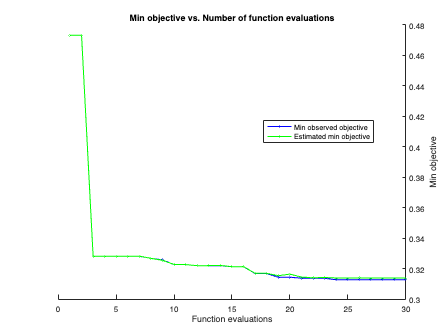

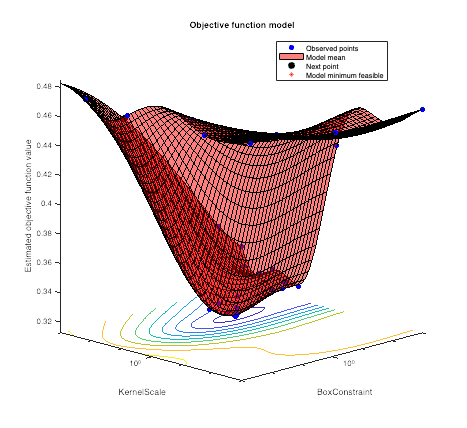


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 350.5662 seconds
Total objective function evaluation time: 316.1512

Best observed feasible point:
    BoxConstraint    KernelScale
    _____________    ___________

       8.6063           13.72   

Observed objective function value = 0.31271
Estimated objective function value = 0.31389
Function evaluation time = 1.7499

Best estimated feasible point (according to models):
    BoxConstraint    KernelScale
    _____________    ___________

       8.6063           13.72   

Estimated objective function value = 0.31389
Estimated function evaluation time = 1.7317



mfccRBFSvmTURMERxLUSMEG95 =   ClassificationSVM
                         ResponseName: 'Y'
                CategoricalPredictors: []
                           ClassNames: [-1 1]
                       ScoreTransform: 'none'
                      NumObservations: 2910
    HyperparameterOptimizationResults: [1×1 BayesianOptimization]
                                Alpha: [1936×1 double]
                                 Bias: 0.6003
                     KernelParameters: [1×1 struct]
                       BoxConstraints: [2910×1 double]
                      ConvergenceInfo: [1×1 struct]
                      IsSupportVector: [2910×1 logical]
                               Solver: 'SMO'


  Properties, Methods


mfccLinearSvmTURMERxLUSMEG95 = fitcsvm(XTrain95,YTrain,'KernelFunction','linear',...
    'Standardize',true,'ClassNames',[-1,1]);
c = cvpartition(size(XTrain95,1),'KFold',7);
opts = struct('CVPartition',c,'AcquisitionFunctionName','expected-improvement-plus');
mfccRBFSvmTURMERxLUSMEG95 = fitcsvm(XTrain95,YTrain,'KernelFunction','rbf', ...
    'OptimizeHyperparameters','auto', 'ClassNames',[-1,1], ...
    'HyperparameterOptimizationOptions',opts)

[XTrain99,mfccCoeffs99Exp3] = projectPCA(XTrain,99);

mfccLinearSvmTURMERxLUSMEG99 = fitcsvm(XTrain99,YTrain,'KernelFunction','linear',...
    'Standardize',true,'ClassNames',[-1,1]);

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | BoxConstraint|  KernelScale |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |     0.46701 |      2.8837 |     0.46701 |     0.46701 |        9.118 |    0.0037556 |
|    2 | Best   |      0.3299 |      5.6308 |      0.3299 |      0.3368 |       644.12 |       566.37 |
|    3 | Accept |     0.44021 |      14.966 |      0.3299 |     0.32991 |       801.06 |      0.53591 |
|    4 | Accept |      0.4732 |      1.3736 |      0.3299 |      0.3299 |     0.025539 |      0.12125 |
|    5 | Accept |      0.4732 |      1.6382 |      0.3299 |     0.32991 |     0.002026 |       109.69 |
|    6 | Accept |     0.35773 |      1.9626 |      0.3299 |     

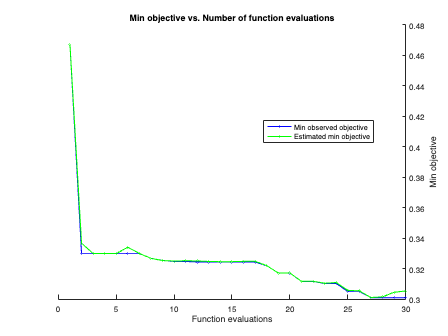

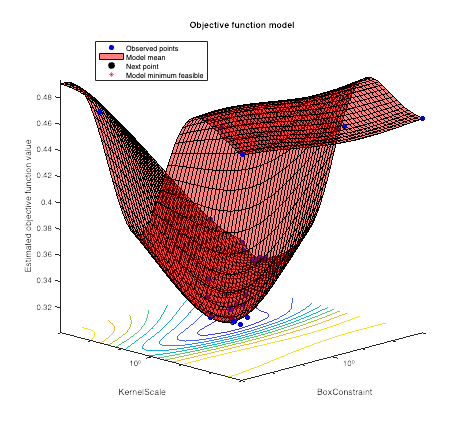


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 194.2682 seconds
Total objective function evaluation time: 164.5462

Best observed feasible point:
    BoxConstraint    KernelScale
    _____________    ___________

       3.2659          3.5234   

Observed objective function value = 0.30103
Estimated objective function value = 0.30537
Function evaluation time = 1.9275

Best estimated feasible point (according to models):
    BoxConstraint    KernelScale
    _____________    ___________

       3.2659          3.5234   

Estimated objective function value = 0.30537
Estimated function evaluation time = 1.9642



mfccRBFSvmTURMERxLUSMEG99 =   ClassificationSVM
                         ResponseName: 'Y'
                CategoricalPredictors: []
                           ClassNames: [-1 1]
                       ScoreTransform: 'none'
                      NumObservations: 2910
    HyperparameterOptimizationResults: [1×1 BayesianOptimization]
                                Alpha: [2179×1 double]
                                 Bias: -0.0304
                     KernelParameters: [1×1 struct]
                       BoxConstraints: [2910×1 double]
                      ConvergenceInfo: [1×1 struct]
                      IsSupportVector: [2910×1 logical]
                               Solver: 'SMO'


  Properties, Methods


c = cvpartition(size(XTrain99,1),'KFold',7);
opts = struct('CVPartition',c,'AcquisitionFunctionName','expected-improvement-plus');
mfccRBFSvmTURMERxLUSMEG99 = fitcsvm(XTrain99,YTrain,'KernelFunction','rbf', ...
    'OptimizeHyperparameters','auto', 'ClassNames',[-1,1], ...
    'HyperparameterOptimizationOptions',opts)

accuracyFreqRangeExperiment3 = {};
TURMER_mfccTest = buildFeatureMatrix(class1,mfccLength,'test',false,freqExperiment3Range);
LUSMEG_mfccTest = buildFeatureMatrix(class2,mfccLength,'test',false,freqExperiment3Range);
testMatrix = {TURMER_mfccTest; LUSMEG_mfccTest};
testMatrix95 = {TURMER_mfccTest * mfccCoeffs95Exp3; LUSMEG_mfccTest * mfccCoeffs95Exp3};
testMatrix99 = {TURMER_mfccTest * mfccCoeffs99Exp3; LUSMEG_mfccTest * mfccCoeffs99Exp3};
testMatrices = {testMatrix;testMatrix95;testMatrix99};
modelsFull = {mfccLinearSvmTURMERxLUSMEG;mfccRBFSvmTURMERxLUSMEG};
models95 = {mfccLinearSvmTURMERxLUSMEG95;mfccRBFSvmTURMERxLUSMEG95};
models99 = {mfccLinearSvmTURMERxLUSMEG99;mfccRBFSvmTURMERxLUSMEG99};
models = {modelsFull;models95;models99};
for i = 1:3 % var
    for j = 1:2 % model type
        t1 = testMatrices{i}{1};
        t2 = testMatrices{i}{2};
        m = models{i}{j};
        acc1 = testModel(t1,-1,m);
        acc2 = testModel(t2,1,m);
        accuracyFreqRangeExperiment3{j,i} = [acc1,acc2];
    end
end

mfccTableFreqRangeExperiment3 = table();
mfccTableFreqRangeExperiment3.('Full model') = accuracyFreqRangeExperiment3(:,1);
mfccTableFreqRangeExperiment3.('95% var PCA') = accuracyFreqRangeExperiment3(:,2);
mfccTableFreqRangeExperiment3.('99% var PCA') = accuracyFreqRangeExperiment3(:,3);
mfccTableFreqRangeExperiment3.Properties.RowNames = {'Linear','RBF'};
% mfccTableFreqRangeExperiment2

fprintf('Accuracy for default BandEdges (50-20000Hz)');

Accuracy for default BandEdges (50-20000Hz)

mfccTableFullFreqRange

mfccTableFullFreqRange = 2×3 table
                 Full model           95% var PCA          99% var PCA   
              _________________    _________________    _________________

    Linear    {[0.7133 0.7533]}    {[0.5200 0.9600]}    {[0.4933 0.9800]}
    RBF       {[0.8600 0.5133]}    {[0.7067 0.6600]}    {[0.6800 0.6067]}


fprintf('Accuracy for limited BandEdges range (500-12000Hz)');

Accuracy for limited BandEdges range (500-12000Hz)

mfccTableFreqRangeExperiment1

mfccTableFreqRangeExperiment1 = 2×3 table
                 Full model           95% var PCA          99% var PCA   
              _________________    _________________    _________________

    Linear    {[0.7133 0.7267]}    {[0.5200 0.9600]}    {[0.4933 0.9800]}
    RBF       {[0.8467 0.5600]}    {[0.6600 0.6933]}    {[0.7000 0.6200]}


fprintf('Accuracy for extended BandEdges range (50-22050Hz)');

Accuracy for extended BandEdges range (50-22050Hz)

mfccTableFreqRangeExperiment2

mfccTableFreqRangeExperiment2 = 2×3 table
                 Full model           95% var PCA          99% var PCA   
              _________________    _________________    _________________

    Linear    {[0.7800 0.8200]}    {[0.5200 0.9600]}    {[0.4933 0.9800]}
    RBF       {[0.9133 0.6133]}    {[0.6733 0.6200]}    {[0.6667 0.5533]}


# ----- Helper Functions -----

function featureMatrix = buildFeatureMatrix(birdID,mfccLength,type,sampleLimit,bandEdges)
arguments
birdID
mfccLength = 18
type = 'train'
sampleLimit = false
bandEdges = false
end
directoryPath = sprintf('samples/%s/syllables/%s',birdID,type);
fileList = dir(fullfile(directoryPath, '*.wav'));
if sampleLimit
    limit = sampleLimit;
else
    limit = numel(fileList);
end
featureMatrix = zeros(limit,mfccLength*14*3);
for ii = 1:limit
    filePath = fullfile(directoryPath, fileList(ii).name);
    [syllable, fs] = audioread(filePath); 
    featureMatrix(ii,:) = extractMfcc(syllable,fs,mfccLength,bandEdges);
end
end